clear all;
close all;
clc;

%%Module 1 starts here

%Taking input RAW file as noisy Signal
inputFile = 'noisySignal.wav';
Fs = 8000;
inputSig = audioread(inputFile);
[inputSigSize, numSig] = size(inputSig);

%Taking clean Signal input
cleanFile = 'cleanSignal.wav';
cleanSig = audioread(cleanFile);

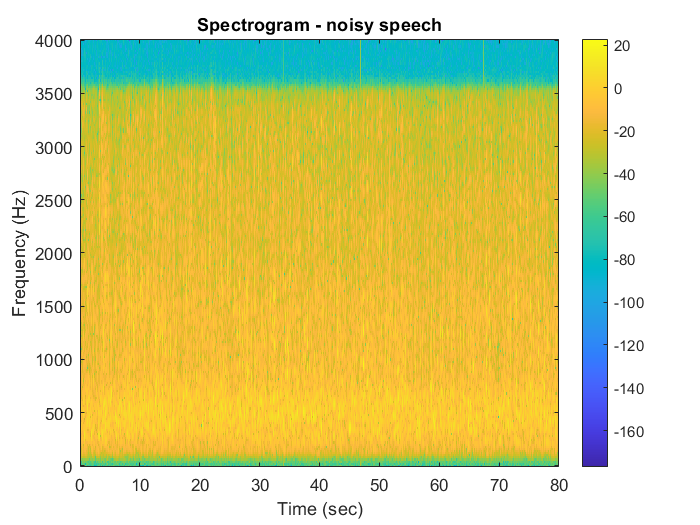

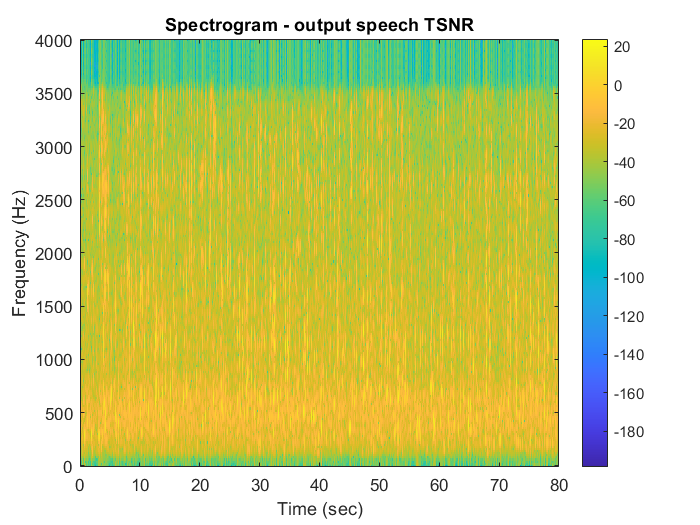

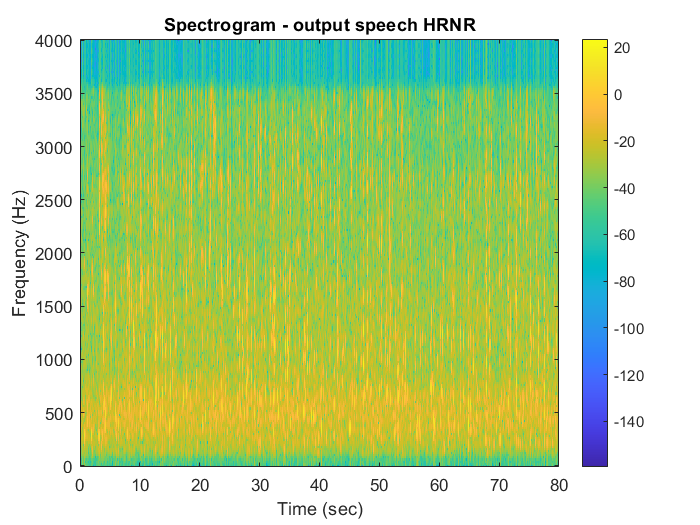

%Wiener Noise Reduction Technique
%Using Two Step Noise Reduction (TSNR) Method and Harmonic Regeneration Noise
%Reduction (HRNR) Method
[esTSNR, esHRNR] = WienerNoiseReduction(inputSig, Fs);

%Wiener-TSNR Method Output
%sound(esTSNR, Fs);
audiowrite('wTSNRoutput.wav', esTSNR, Fs);

%Wiener-HRNR Method Output
%sound(esHRNR, Fs);
audiowrite('wHRNRoutput.wav', esHRNR, Fs);

%Spectral Signal Subtraction (SSS) Method Output
sssOut = SpectralSignalSubtraction(inputSig, Fs);
audiowrite('sssOutputSignal.wav', sssOut, Fs);

%Module 1 ends here

%Module 2 starts here

%Signal Subspace Approach - Spectral Amplitude Minimum Mean Square Error
%Method Output
ssaOut = MMSESTSA84(inputSig, Fs);

audiowrite('ssaOutputSignal.wav', ssaOut, Fs);

%Module 2 ends here

%Performance Evaluation using MSE and PSNR as evaluation metrics

%Mean Square Error (MSE) Calculations for each method
wTSNRmse = sum(sqrt(((esTSNR - cleanSig).^2)/inputSigSize))

wTSNRmse = 15.1985

wHRNRmse = sum(sqrt(((esHRNR - cleanSig).^2)/inputSigSize))

wHRNRmse = 15.1910

sssOUTmse = sum(sqrt(((sssOut - cleanSig(1:length(sssOut))).^2)/length(sssOut)))

sssOUTmse = 17.5744

ssaOUTmse = sum(sqrt(((ssaOut - cleanSig(1:length(ssaOut))).^2)/length(ssaOut)))

ssaOUTmse = 21.2466

%Peak Signal-To-Noise Ratio (PSNR) Calculations for each method
wTSNRpsnr = 20*log10(max(abs(esTSNR))/wTSNRmse)

wTSNRpsnr = -27.5392

wHRNRpsnr = 20*log10(max(abs(esHRNR))/wHRNRmse)

wHRNRpsnr = -27.5349

sssOUTpsnr = 20*log10(max(abs(sssOut))/sssOUTmse)

sssOUTpsnr = -27.0805

ssaOUTpsnr = 20*log10(max(abs(ssaOUTmse))/ssaOUTmse)

ssaOUTpsnr = 0

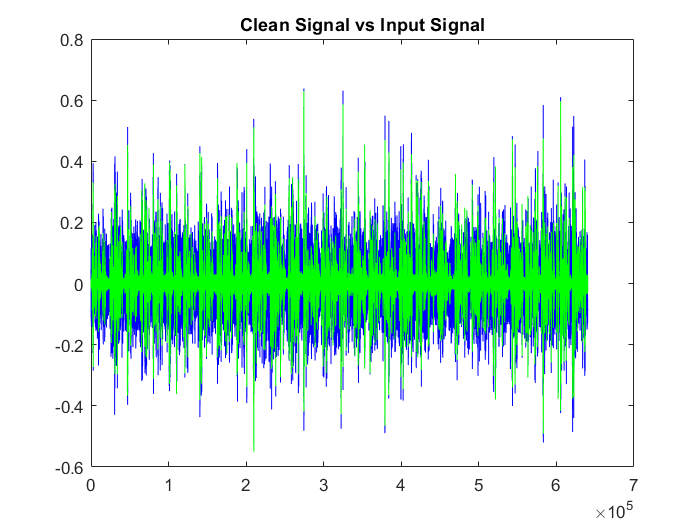

%Time Domain Plots of Clean Signals vs Restored Signals
figure(1);
plot(inputSig, 'blue');
hold on;
plot(cleanSig, 'green');
hold off;
title('Clean Signal vs Input Signal');

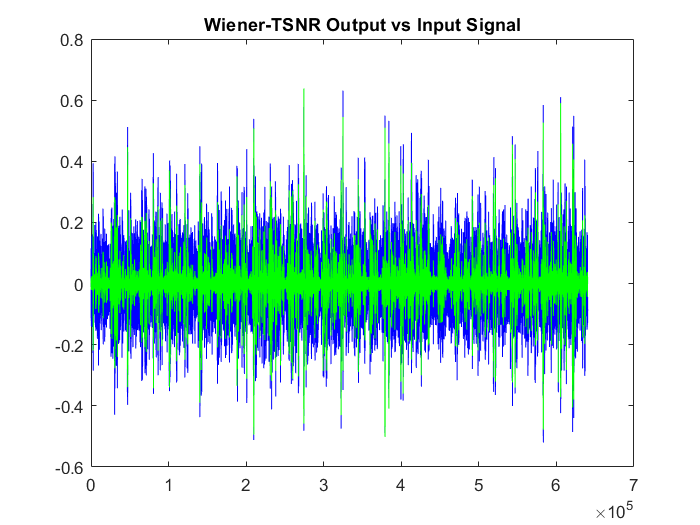


figure(2);
plot(inputSig, 'blue');
hold on;
plot(esTSNR, 'green');
hold off;
title('Wiener-TSNR Output vs Input Signal');

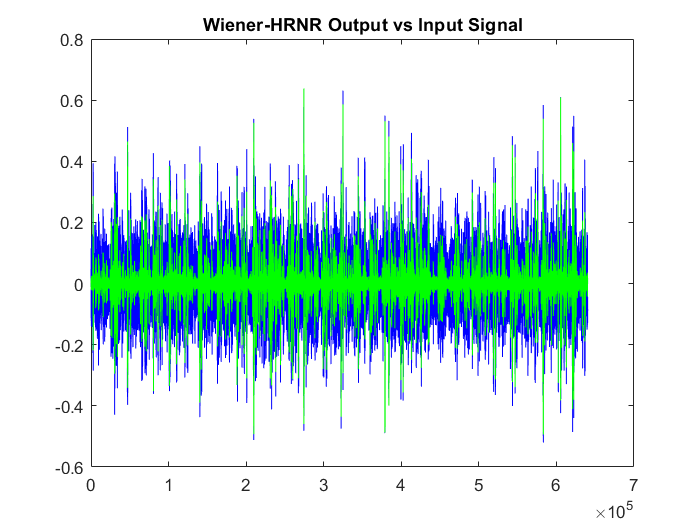


figure(3);
plot(inputSig, 'blue');
hold on;
plot(esHRNR, 'green');
hold off;
title('Wiener-HRNR Output vs Input Signal');

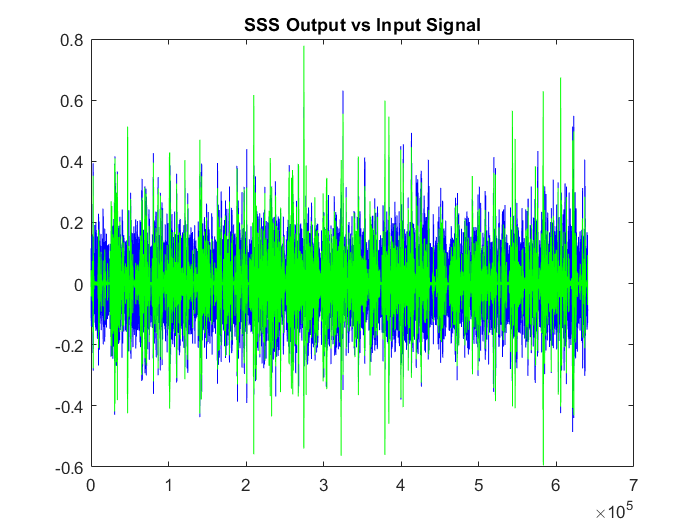


figure(4);
plot(inputSig, 'blue');
hold on;
plot(sssOut, 'green');
hold off;
title('SSS Output vs Input Signal');

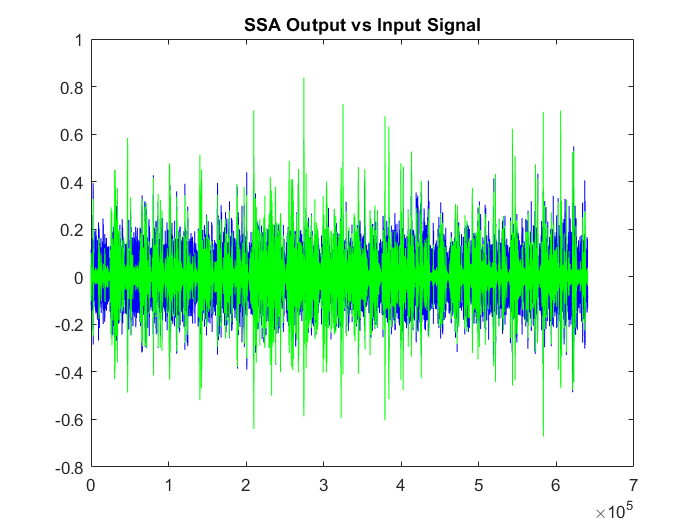


figure(5);
plot(inputSig, 'blue');
hold on;
plot(ssaOut, 'green');
hold off;
title('SSA Output vs Input Signal');